# Sessió 7

## Xavier Martín Ballesteros i Adrià Cabeza Sant'Anna

im = imread('danaus.tif');
imshow(im), title('Imatge Original')

Dilatació

ee = strel('disk',1);
dil = imdilate(im, ee);
figure, imshow(dil), title('Imatge dilatada')

Erosió

ero = imerode(im,ee);
figure, imshow(ero), title('Imatge erosionada')

Contorn extern 

grad = imsubtract(dil,im);
figure, imshow(grad, []), title('Contorn extern')

Controrn doble

grad2 = imsubtract(dil,ero);
figure,imshow(grad2,[]), title('Contorn doble')
close all

Opening i close 

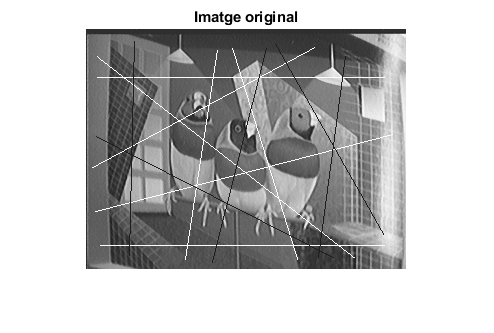

%opening elimina petites estructures blanques
%close elimina petites estructures negres
im = imread('Birds.tif') ;
imshow(im), title('Imatge original')

Opening 

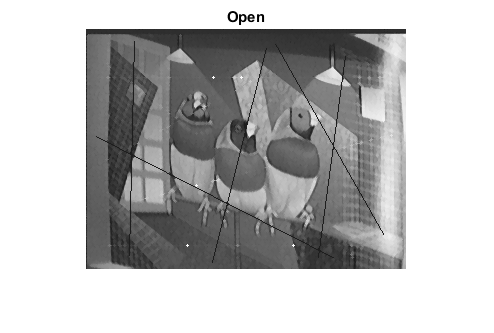

op = imopen(im,ee);
figure, imshow(op), title('Open')

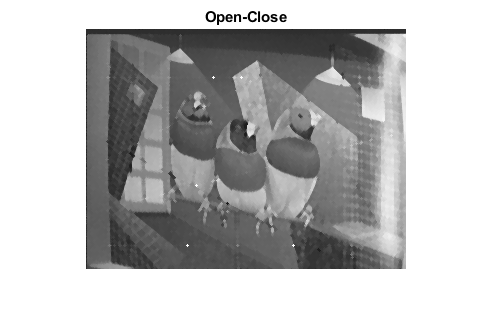

opcl= imclose(op,ee);
figure, imshow(opcl),title('Open-Close')

### Bottom hat

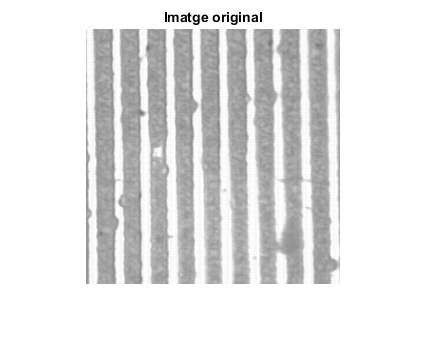

im = imread('r4x2_256.tif');
imshow(im), title('Imatge original')

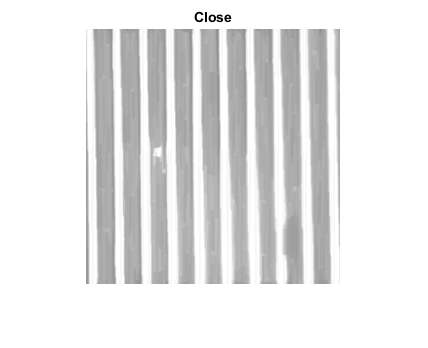


ee = strel('line', 25,90);
cl = imclose(im,ee);
figure,imshow(cl),title('Close')

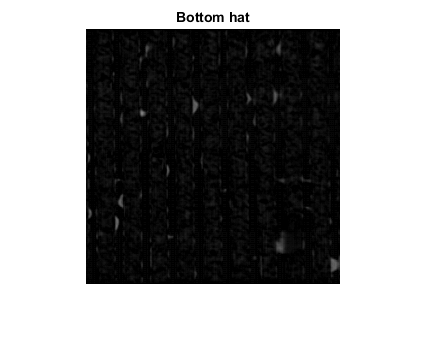

res = imsubtract(cl,im);
figure, imshow(res), title('Bottom hat')

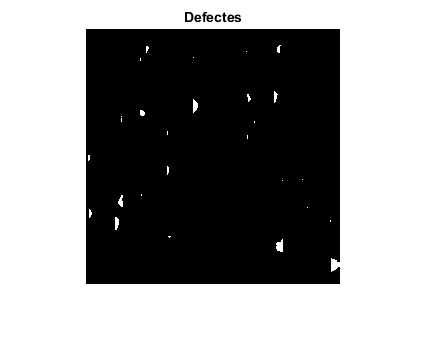


bw = im2bw(res,0.2);
figure, imshow(bw), title('Defectes');

### Opening per atributs

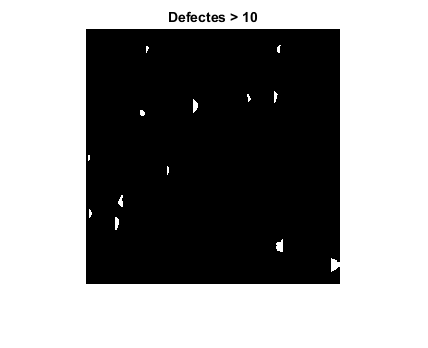

def = bwareaopen(bw, 10);
figure, imshow(def), title('Defectes > 10')

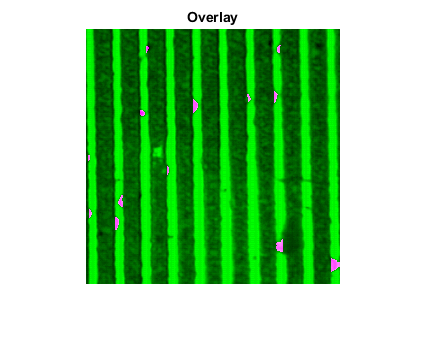

overlay = imfuse(im, def);
figure, imshow(overlay) , title('Overlay')

### Exemple control de qualitat

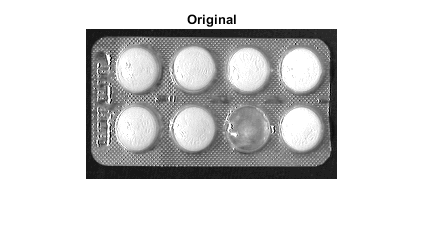

im = imread('astablet.tif');
imshow(im), title('Original')

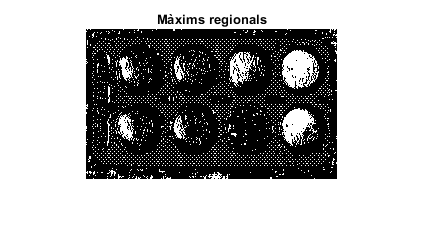

rm = imregionalmax(im);
figure, imshow(rm), title('Màxims regionals')

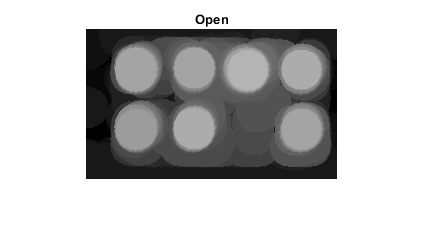


ee = strel('disk',20,0);
op = imopen(im,ee);
figure,imshow(op), title('Open')

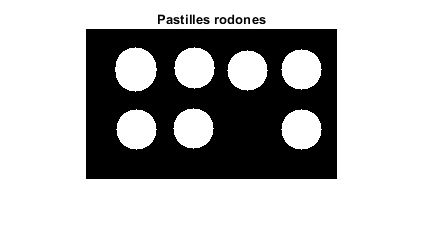

rm2 = imregionalmax(op);
figure, imshow(rm2), title("Pastilles rodones")



% mark = rm2;
% mark(2:end-1,2:end-1)=0;
% rec = imreconstruct(mark,rm2);
% figure, imshow(rec), title('Reconstrucció')
% res = imsubtract(rm2,rec);
% figure, imshow(res), title('sencer')

## Segmentació: Watershed

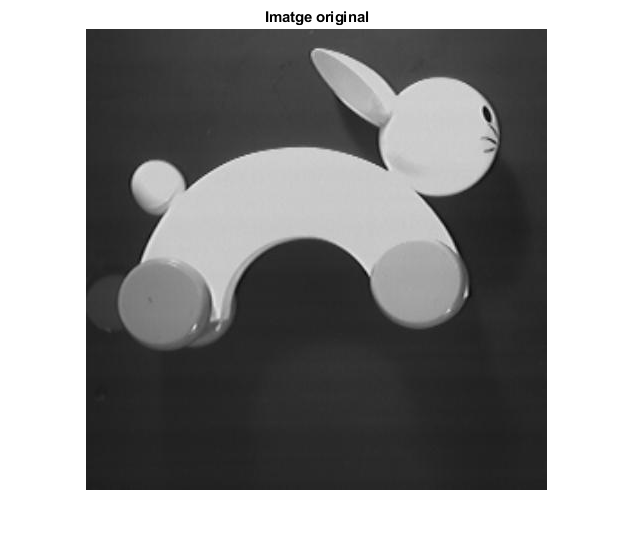

im= imread('rabbit.jpg');
imshow(im),title('Imatge original');

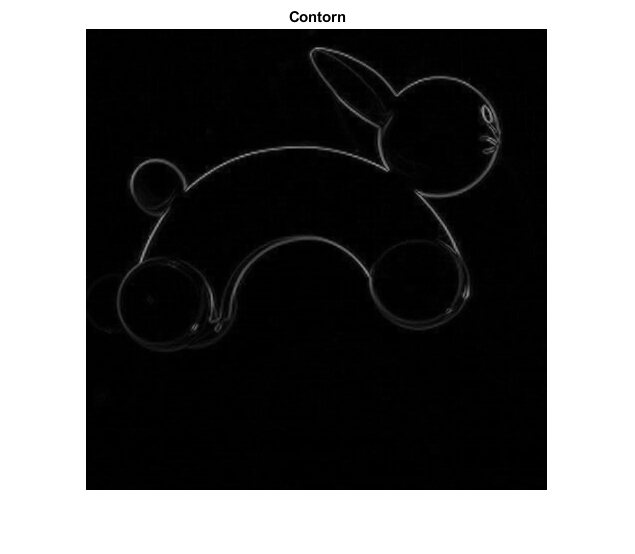

ee = strel('disk',1);
grad= imsubtract(imdilate(im,ee),imerode(im,ee));
figure, imshow(grad), title('Contorn');

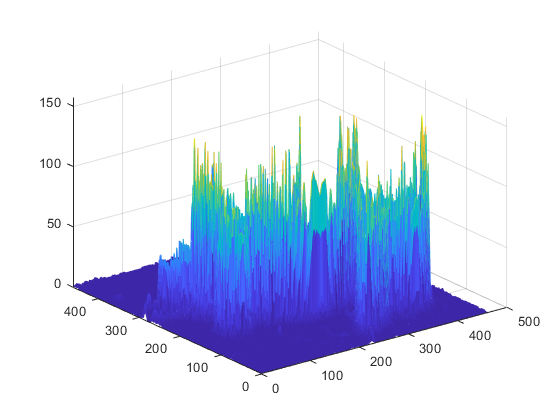

figure, mesh(grad) %surf(grad)

segm1 = watershed(grad);

#### Problemes de sobresegmentació 

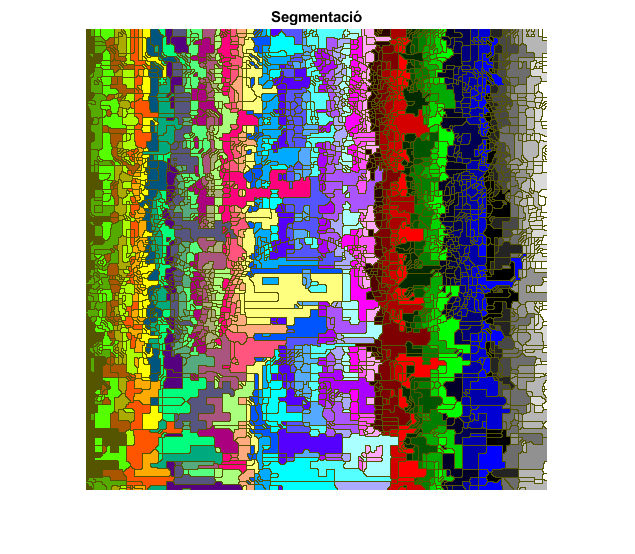

figure,imshow(segm1,[]),title('Segmentació'), colormap('colorcube')

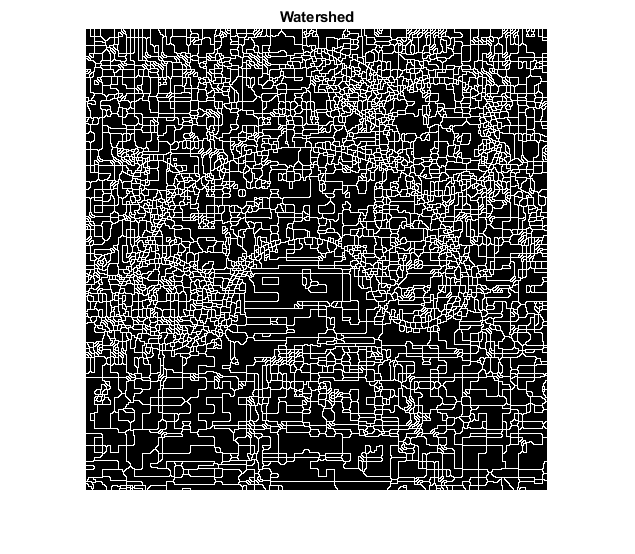

figure,imshow(segm1==0),title('Watershed')

nsegmentacions= max(segm1(:))

nsegmentacions = uint16
3476

#### Solució

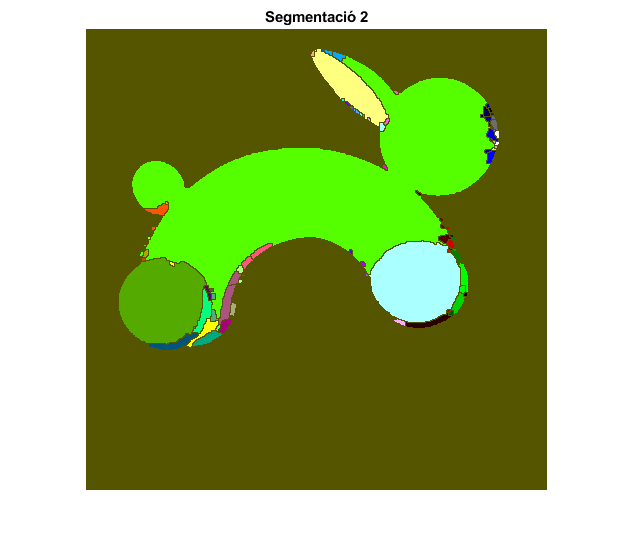

grad2 = imhmin(grad,5);
segm2= watershed(grad2);
figure,imshow(segm2,[]), title('Segmentació 2'), colormap('colorcube')

nsegmentacions= max(segm2(:))

nsegmentacions = uint8
94

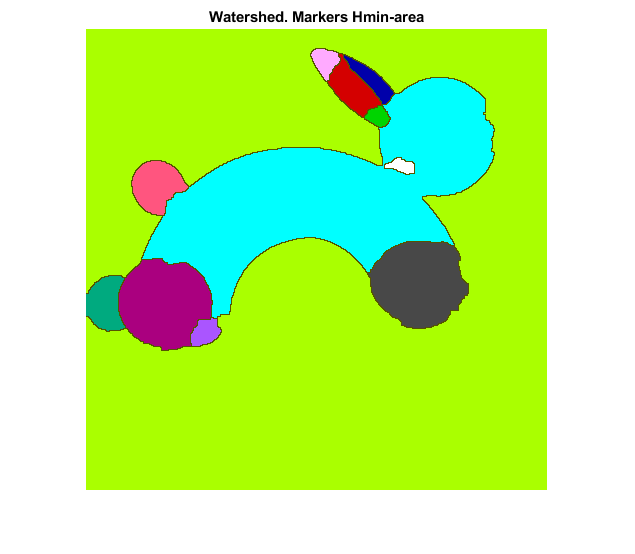

ee = strel('disk', 5);
grad3 = imclose(grad2, ee);
segm3 = watershed(grad3);
figure, imshow(segm3, []), title('Watershed. Markers Hmin-area'), colormap('colorcube')

nsegmentacions= max(segm3(:))

nsegmentacions = uint8
12

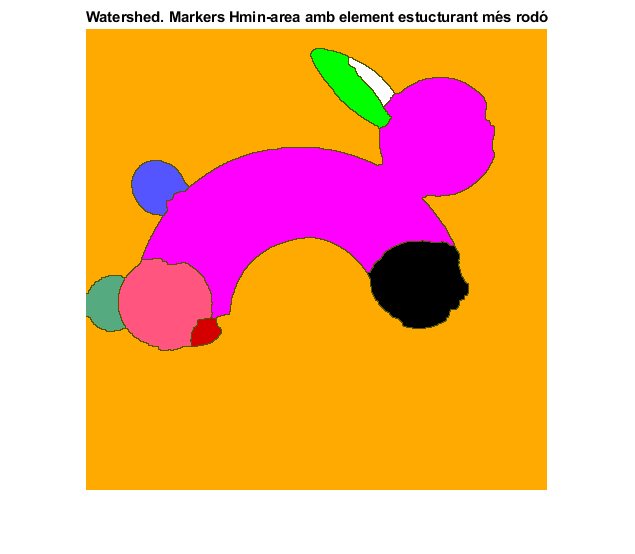


ee = strel('disk', 5, 0);
grad4 = imclose(grad2, ee);
segm4 = watershed(grad4);
figure, imshow(segm4, []), title('Watershed. Markers Hmin-area amb element estucturant més rodó'), colormap('colorcube')

nsegmentacions= max(segm4(:))

nsegmentacions = uint8
9

## Segmentació de touching blobs amb Watershed

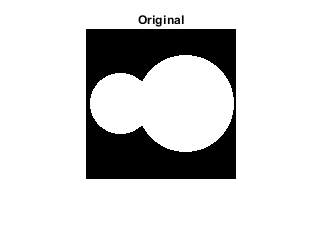

im = imread('touchcell.tif');
figure, imshow(im), title('Original')

#### Watershed sobre la transformada de distància 

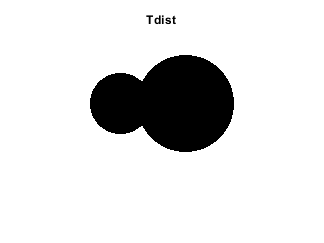

d = bwdist(im);
figure, imshow(d), title('Tdist')

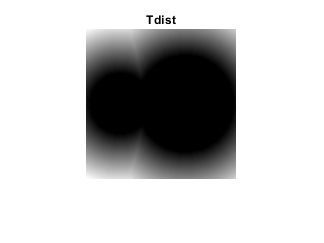

figure, imshow(d,[]), title('Tdist')

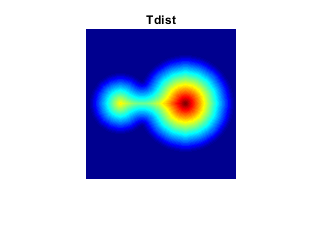

bw = bwdist(~im);
figure, imshow(bw,[]), title('Tdist'), colormap('jet')

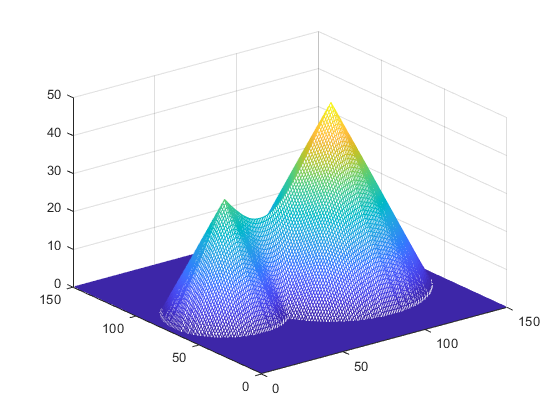

figure, mesh(bw)

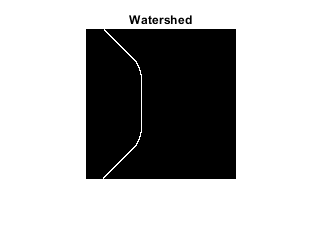

segm = watershed(-bw);
figure,imshow(segm==0), title('Watershed')

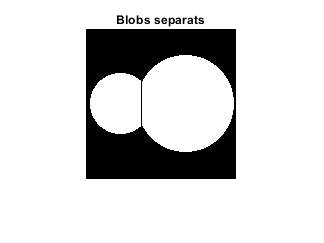

res = im; 
res(segm==0)= 0;
figure, imshow(res), title('Blobs separats')

## Exercici: Segmenteu els grans de cafè

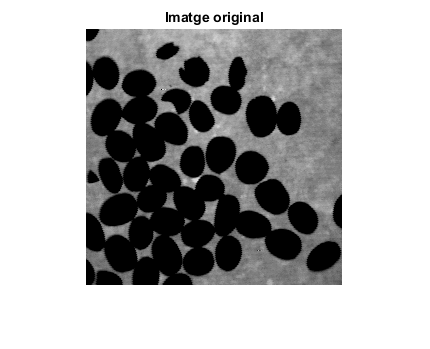

im = imread('cafe.tif');
figure, imshow(im),title('Imatge original')

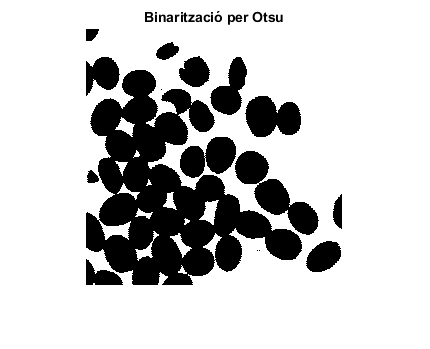


bw = im2bw(im,graythresh(im));
figure,imshow(bw), title('Binarització per Otsu')

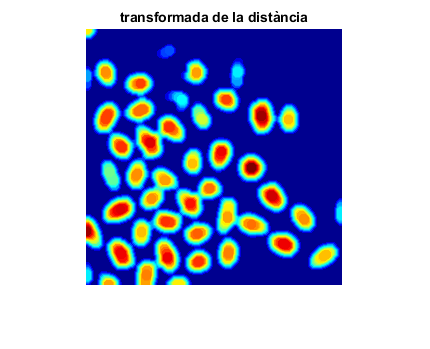


d = bwdist(im);

ee = strel('disk', 5);
op = imopen(d,ee);

figure, imshow(op,[]), colormap('jet'), title('transformada de la distància')

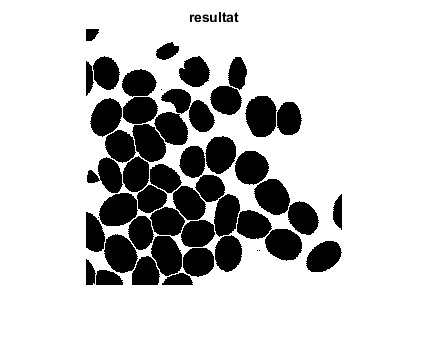

segm = watershed(-op);

res = im;
res(segm==0)=255;
res = imbinarize(res, graythresh(res));
figure,imshow(res), title('resultat')